# Embeddings

Resource: [The You You Are by Dr. Ricken Lazlo Hale, PhD on Apple Books](https://books.apple.com/us/book/the-you-you-are/id6738364141)

### Open-source embedding model

model = documentEmbedding(Model='all-MiniLM-L6-v2'); % or 'all-MiniLM-L12-v2'
quote1a = "What separates man from machine is that machines cannot think for themselves.";
embedding_quote1a = model.embed(quote1a)

embedding_quote1a =     0.0039   -0.0150   -0.0280   -0.0170   -0.0243   -0.0678    0.0578   -0.0246    0.0006   -0.0144    0.0391    0.0092    0.0417   -0.0879    0.0430   -0.0592   -0.0660   -0.0397   -0.0314    0.0044    0.0724    0.0267   -0.0603   -0.0068   -0.0310    0.0683   -0.0407   -0.0076    0.0114   -0.0248    0.0181   -0.0430   -0.0367    0.0093    0.0529    0.0199    0.0243    0.0187    0.0101   -0.1098   -0.0335   -0.0296   -0.0132    0.0001    0.0876    0.1081   -0.0249   -0.0813   -0.0103   -0.0452


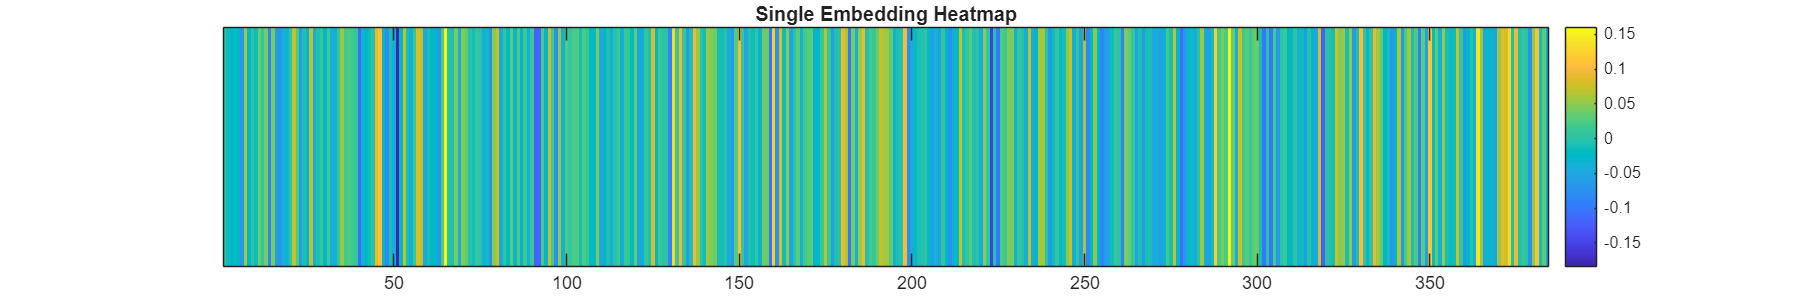

plotSingleEmbedding(embedding_quote1a)

quote1a = "What separates man from machine is that machines cannot think for themselves.";
quote1b = "Also they are made of metal, whereas man is made of skin.";
embedding_quote1a = model.embed(quote1a);
embedding_quote1b = model.embed(quote1b);
distance = dot(embedding_quote1a,embedding_quote1b)

distance = 0.3547

plotAlignedEmbeddings(embedding_quote1a, embedding_quote1b)

### Semantic similarity

Since the norm of the vector embeddings is 1, cosine similarity between the vectors results in a simple dot product.

norm(embedding_quote1b)

ans = 1.0000

dot(embedding_quote1a,embedding_quote1b)

ans = 0.3547

dot(model.embed("Bullies"),model.embed("BULL and LIES"))

ans = 0.4531

quote2 = "Bullies are nothing but BULL and LIES." ;
quote3 = "At the center of industry is (dust).";
dot(model.embed(quote2),model.embed(quote3))

ans = -0.0284

dot(model.embed("industry"),model.embed("dust"))

ans = 0.3065

% Define the paragraph as a string literal using concatenation for readability
paragraph = "It's said that as a child, Wolfgang Mozart killed another boy by slamming his head in a piano." + newline + ...
    "Don't worry, my research for this book has proven the claim untrue." + newline + ...
    "As your heart rate settles though, consider the power an author, heretofore referred to as Me, can hold over a reader, heretofore called You." + newline + ...
    "But what, indeed, is… You? All creatures from the leaping cat to the cowering shrew think of themselves as You, a logical center for the universe." + newline + ...
    "Yet the cat eats the shrew, and we, like Schrödinger, live on to wonder what it means." + newline + ...
    "I'm not asking out of mere politeness. For You, my friend, are no mere consumer of this book, sucking down nouns and adverbs like a plump babe to the teat." + newline + ...
    "In fact, your relationship to this work is far more intimate and profound." + newline + ...
    "You are its subject.";

% Split the paragraph into sentences 
sentences = splitlines(paragraph);

% Select the first sentence 
sentence1 = sentences(1)

sentence1 = "It's said that as a child, Wolfgang Mozart killed another boy by slamming his head in a piano."

Process the whole paragraph in one call

embeddings = model.embed(sentences)

embeddings =     0.0028    0.0890    0.0325    0.0031    0.0286    0.0859    0.0421    0.0474   -0.0152   -0.0094    0.0226   -0.0426   -0.0305   -0.0330   -0.0510   -0.0265   -0.0309    0.0679   -0.0474    0.0078    0.0045    0.0244    0.0339   -0.0331    0.0040    0.0697    0.0311   -0.0476   -0.0013    0.0533   -0.0093   -0.0708   -0.0018   -0.0778   -0.0844   -0.0134    0.0202   -0.0060   -0.0389    0.0206   -0.0318    0.1108   -0.1448    0.0136   -0.0384   -0.0222   -0.0780   -0.1006    0.0134    0.0259
   -0.0120   -0.0089    0.0003    0.0913    0.0021   -0.0226   -0.0261   -0.0467   -0.0523    0.0461    0.0127    0.0639    0.0792   -0.0358   -0.0666   -0.0137   -0.0815   -0.0239    0.0072    0.0033    0.0436    0.0220    0.1052    0.0441    0.0786   -0.1017    0.0192    0.0372   -0.0275   -0.0105   -0.0168    0.1218   -0.0278   -0.0408    0.0470    0.0103    0.0877    0.0098    0.0404    0.0016    0.0585   -0.1222    0.0283   -0.0011   -0.0420    0.0881   -0.0389   -0.0217   -0.

### Vector Search

% Encode the sentence "who are you"
query_sentence = "who are you";
query_embedding = model.embed(query_sentence);
distance = cosineSimilarity(query_embedding,embeddings)

distance =     0.0175    0.1006    0.2865    0.2591    0.0575    0.1728    0.1485    0.3332


[B,I] = sort(distance,"descend")

B =     0.3332    0.2865    0.2591    0.1728    0.1485    0.1006    0.0575    0.0175


I =      8     3     4     6     7     2     5     1


sentences(I)

ans = 8×1 string array
    "You are its subject."
    "As your heart rate settles though, consider the power an author, heretofore referred to as Me, can hold over a reader, heretofore called You."
    "But what, indeed, is… You? All creatures from the leaping cat to the cowering shrew think of themselves as You, a logical center for the universe."
    "I'm not asking out of mere politeness. For You, my friend, are no mere consumer of this book, sucking down nouns and adverbs like a plump babe to the teat."
    "In fact, your relationship to this work is far more intimate and profound."
    "Don't worry, my research for this book has proven the claim untrue."
    "Yet the cat eats the shrew, and we, like Schrödinger, live on to wonder what it means."
    "It's said that as a child, Wolfgang Mozart killed another boy by slamming his head in a piano."


Let's use Facebook AI Similarity Search (FAISS)

d = py.int(384); % Dimension of the embeddings
index = py.faiss.IndexFlatL2(d);
index.add(embeddings)

% Save the index to a file
py.faiss.write_index(index, "you.index");

% Later, load the index from the file
index = py.faiss.read_index("you.index");

% Encode the sentence "who are you"
query_sentence = "who are you";
query_embedding = model.embed(query_sentence);

% Convert query_embedding to a numpy array and reshape to [1, 384]
query_embedding = py.numpy.reshape(query_embedding, py.tuple({py.int(1), d}));

k = py.int(3);  % Number of nearest neighbors to retrieve
res = index.search(query_embedding, k);
distance = double(res{1})

distance =     1.3337    1.4270    1.4818


indices = int64(res{2})

indices = 1×3 int64 row vector
   7   2   3


disp("Nearest neighbors (smaller is better):")

Nearest neighbors (smaller is better):


% Loop over the number of neighbors returned.
% Note: FAISS returns 0-indexed indices, so add 1 for MATLAB indexing.
for i = 1:size(indices, 2)
    idx = indices(1, i) + 1;  
    % Use either sentences{idx} (if sentences is a cell array)
    % or sentences(idx) (if sentences is a string array)
    fprintf("Sentence: %s, Distance: %f\n", sentences{idx}, distance(1, i));
end

Sentence: You are its subject., Distance: 1.333668
Sentence: As your heart rate settles though, consider the power an author, heretofore referred to as Me, can hold over a reader, heretofore called You., Distance: 1.427042
Sentence: But what, indeed, is… You? All creatures from the leaping cat to the cowering shrew think of themselves as You, a logical center for the universe., Distance: 1.481814


### Utils

Function to visualize a single embedding as a heatmap

function plotSingleEmbedding(embedding)
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(embedding);
    
    % Set a colormap 
    colormap("parula");
    
    % Remove y-axis ticks
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Single Embedding Heatmap');
end

Function to plot embeddings aligned

function plotAlignedEmbeddings(embedding1, embedding2)
    % Stack the embeddings for aligned visualization 
    % (each embedding is assumed to be a row vector)
    aligned_embeddings = [embedding1; embedding2];
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(aligned_embeddings);
    
    % Set colormap
    colormap("parula");
    
    % Set the y-axis ticks to correspond to the two embeddings
    set(gca, 'YTick', [1, 2], 'YTickLabel', {'Embedding 1', 'Embedding 2'});
    
    % Remove x-axis ticks
    set(gca, 'XTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Aligned Embeddings Heatmap');
end

Function to compare one embedding over another

function plotDifferenceEmbeddings(embedding1, embedding2)
    % Compute the difference between the embeddings
    difference = embedding1 - embedding2;
    
    % Create a figure with a custom size (in pixels)
    figure('Position', [100, 100, 1200, 200]);

    % Display the data as a heatmap
    imagesc(difference);
    
    % Set colormap 
    colormap(parula);
    
    % Remove x-axis and y-axis ticks for cleaner visualization
    set(gca, 'XTick', []);
    set(gca, 'YTick', []);
    
    % Add a colorbar to the side of the heatmap
    colorbar;
    
    % Set the title of the plot
    title('Embedding Difference Heatmap');
end